addpath("C:\Users\agori\Documents\MATLAB\3D-Sea-Ice\ExtractClouds");
addpath("C:\Users\agori\Documents\MATLAB\3D-Sea-Ice\CoarseAlignment");
addpath("C:\Users\agori\Documents\MATLAB\3D-Sea-Ice\DataAnalysis\");
%load("FilteredP3Clean.mat");
%load("FilteredP3.mat")
load("C:\Users\agori\Documents\MATLAB\MSc\bigfiles\outputTest\AfterICP\afterFilter.mat");

filtCloud=pccat(arrFiltered);
filtCloudclean=pcdownsample(filtCloud,"gridAverage",0.01);

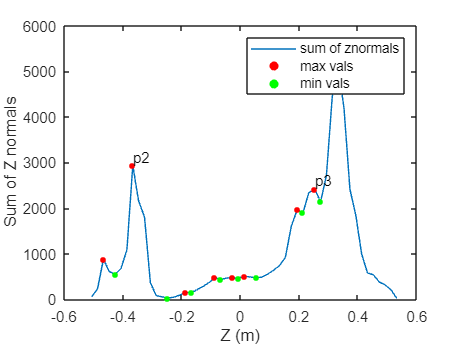

[sortedPOI,p1Index,p2Index,p3Index] = zNormsAnalysis(filtCloudclean, 'true');

disp(sortedPOI(p2Index+1))

   -0.2471



pcTotalCake=cropCloud(filtCloudclean,[-inf,inf],[-inf,inf],[sortedPOI(p2Index+1), inf]);


%pcTotalCake=cropCloud(filtCloudclean,[-inf,inf],[-inf,inf],[sortedPOI(p2Index+1), inf]);
pcTotalCake=cropCloud(filtCloudclean,[-inf,inf],[-inf,inf],[sortedPOI(p3Index+1), inf]);

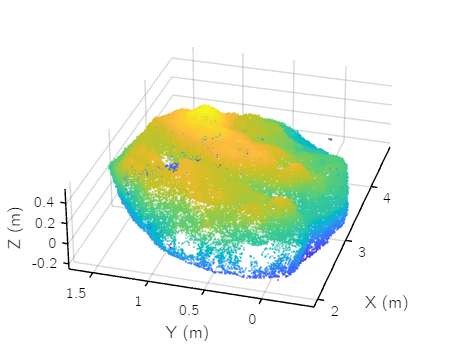

%pcTotalCake=cropCloud(pcTotalCake,[-inf, 4.25],[-inf,inf],[-inf,inf]);
pcDisplay(pcTotalCake);

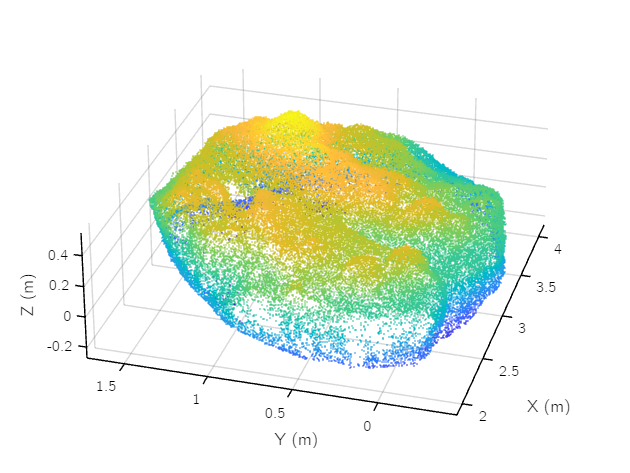

pcTotalCake=cropCloud(pcTotalCake,[-inf, 4.25],[-inf,inf],[-inf,inf]);
pcDisplay(pcTotalCake);

% mesh4=pc2surfacemesh(pcTotalCake,'poisson',4);
% mesh5=pc2surfacemesh(pcTotalCake,'poisson',5);
% mesh6=pc2surfacemesh(pcTotalCake,'poisson',6);
% meshList={mesh4,mesh5,mesh6};

% figure('Color','w','Units','centimeters','Position',[2 2 17 9]);
% 
% t = tiledlayout(2,3, ...
%     'TileSpacing','none', ...
%     'Padding','tight');
% 
% for k = 1:3
% 
%     nexttile
% 
%     hold on
% 
%     patch('Vertices',meshList{k}.Vertices,...
%           'Faces',meshList{k}.Faces,...
%           'FaceColor',[0.8 0.8 1],...
%           'EdgeColor','none');
% 
%     axis equal
%     axis off
%     view(3)
% 
%     lighting gouraud
%     camlight headlight
% 
%     set(gca, 'FontName', 'CMU Bright');
% 
%     hold off
% end

% meshList = { ...
%     readSurfaceMesh("2BlocksDepth3.ply"), ...
%     readSurfaceMesh("2BlocksDepth4.ply"), ...
%     readSurfaceMesh("2BlocksDepth5.ply"), ...
%     readSurfaceMesh("2BlocksDepth6.ply"), ...
%     readSurfaceMesh("2BlocksDepth7.ply"), ...
%     readSurfaceMesh("2BlocksDepth8.ply") };

zvals=pcTotalCake.Location(:,3);
zmin=pcTotalCake.ZLimits(1,1)

zmin = single
-0.2674

zmax=pcTotalCake.ZLimits(1,2)

zmax = single
0.5516

maxdiff=zmax-zmin

maxdiff = single
0.8190

maxZCloud = filterMaxZ(pcTotalCake, 0.02);
pcColoured = normColourCloud(maxZCloud);

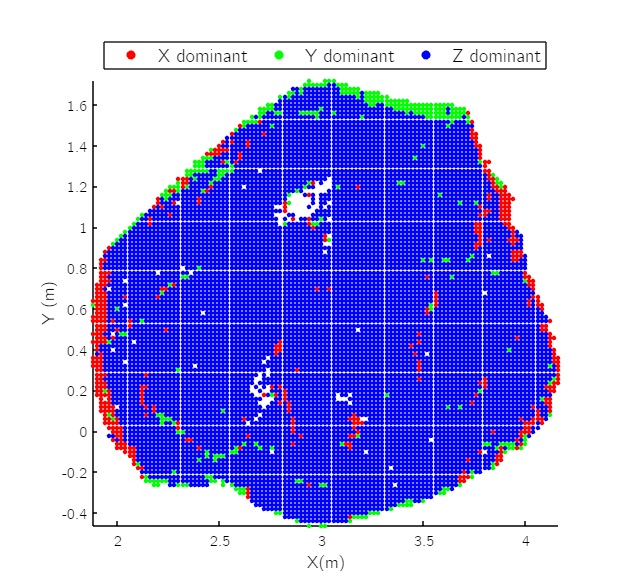


fig=figure;
pcDisplay(pcColoured,'MarkerSize', 80)
set(gca, 'XGrid', 'off', 'YGrid', 'off', 'ZGrid', 'off');
set(gcf, 'Color', 'w');
view(2); 
%fig.Color = 'white';
fig.Position(4) = fig.Position(4)+100;  % 25% taller
axis equal;
zlabel('');
xlabel('X(m)')
daspect([1 1 1]);          % equal data aspect ratio
pbaspect([1 1 1]);         % equal plot box size
set(gca,'Projection','orthographic');  % removes perspective distortion
set(gca, 'XColor', 'k', 'YColor', 'k');
set(gca, 'Color', 'w');       % axes background
set(gcf, 'Color', 'w');       % figure background
hold on;

h1 = scatter(nan, nan, 50, 'r', 'filled');   % X-dominant
h2 = scatter(nan, nan, 50, 'g', 'filled');   % Y-dominant
h3 = scatter(nan, nan, 50, 'b', 'filled');   % Z-dominant


lgd=legend([h1 h2 h3], {'X dominant', 'Y dominant', 'Z dominant'}, 'Location','northoutside', 'Orientation','horizontal');
lgd.Color = 'w';     
lgd.TextColor = 'k'; 
lgd.FontSize = 12;
hold off;

pcTop = extractTopCloud(maxZCloud);


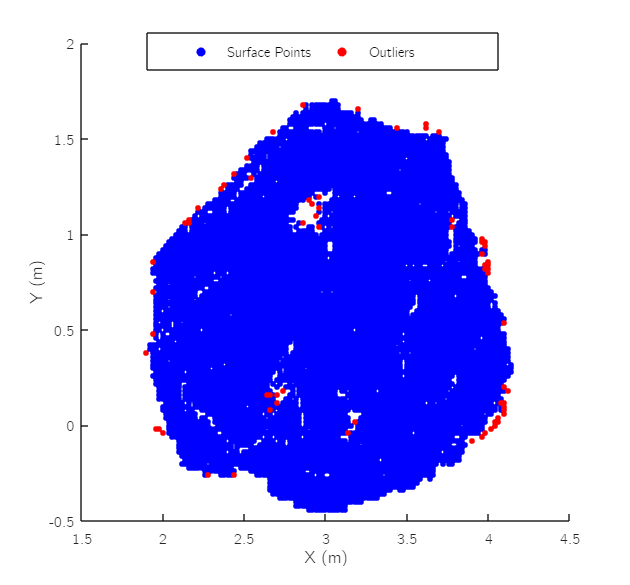

pcTopFiltered=outlierRemoval(pcTop,10,'true');
myfig=gcf;
set(gca, 'FontName', 'CMU Bright');


legend('Surface Points', 'Outliers', 'Location','north','Orientation','horizontal')
xlabel('X (m)');
ylabel('Y (m)');

legend("Position", [0.23458,0.88111,0.5575,0.063333])

pcTopFilled = fillTopCloud(pcTopFiltered, maxZCloud,0.02);

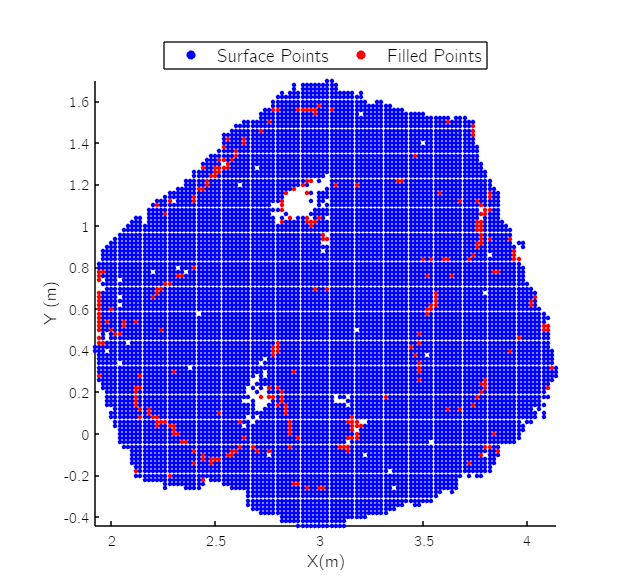


fig=figure;
pcDisplay(pcTopFilled,'MarkerSize', 80)
set(gca, 'XGrid', 'off', 'YGrid', 'off', 'ZGrid', 'off');

view(2); 
fig.Color = 'black';
fig.Position(4) = fig.Position(4)+100;  % 25% taller
axis equal;
zlabel('');
xlabel('X(m)')
daspect([1 1 1]);          % equal data aspect ratio
pbaspect([1 1 1]);         % equal plot box size
set(gca,'Projection','orthographic');  % removes perspective distortion
set(gca, 'XColor', 'k', 'YColor', 'k');
set(gca, 'Color', 'w');       % axes background
set(gcf, 'Color', 'w');       % figure background
hold on;

h1 = scatter(nan, nan, 50, 'b', 'filled');   % X-dominant
h2 = scatter(nan, nan, 50, 'r', 'filled');   % Y-dominant


lgd=legend([h1 h2], {'Surface Points', 'Filled Points'}, 'Location','northoutside', 'Orientation','horizontal');
lgd.Color = 'w';     
lgd.TextColor = 'k'; 
lgd.FontSize = 12;
hold off;

[F,X,Y]=interpolateCloud(pcTopFilled,0.02);



Fclean=F(~isnan(F));
stdTotal=std(Fclean)

stdTotal = 0.0823

meanTotal=mean(Fclean)

meanTotal = 0.3210

% Z = your 110x111 matrix with NaNs for missing ice

% Extract valid points
h = Fclean;  % column vector of all height values

% --- Robust summary statistics ---
mean_h     = mean(h);
median_h   = median(h);
std_h      = std(h);
mad_h      = mad(h, 1);       % Median Absolute Deviation (scaled)
skew_h     = skewness(h);
kurt_h     = kurtosis(h);

% Display numeric results
fprintf('Height Statistics:\n');

Height Statistics:


fprintf('  Mean:      %.4f\n', mean_h);

  Mean:      0.3210


fprintf('  Median:    %.4f\n', median_h);

  Median:    0.3345


fprintf('  STD:       %.4f\n', std_h);

  STD:       0.0823


fprintf('  MAD:       %.4f\n', mad_h);

  MAD:       0.0510


fprintf('  Skewness:  %.4f\n', skew_h);

  Skewness:  -0.2574


fprintf('  Kurtosis:  %.4f\n', kurt_h);

  Kurtosis:  3.2381


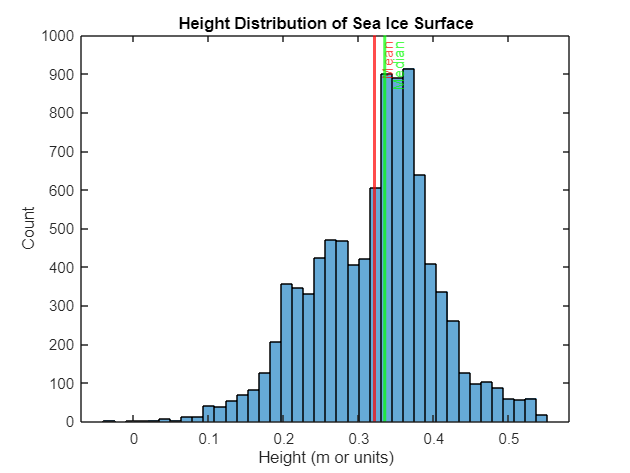


% --- Histogram plot ---
figure;
histogram(h, 40);      % 40 bins (adjust as needed)
xlabel('Height (m or units)');
ylabel('Count');
title('Height Distribution of Sea Ice Surface');

% Add vertical lines for mean & median
hold on;
xline(mean_h,   'r', 'LineWidth', 2, 'Label','Mean');
xline(median_h, 'g', 'LineWidth', 2, 'Label','Median');
hold off;

histogram(Fclean)

boxplot(Fclean)

%n=110;
n=109;
cutoff=25;
output = interestPeaks(F,X,Y,n,cutoff);

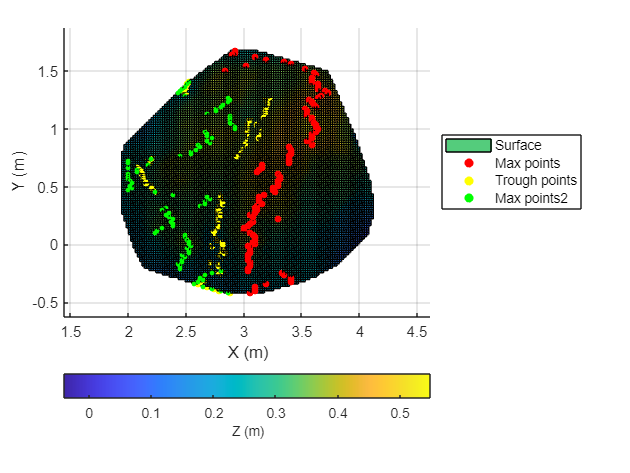

figure
surf(X, Y, F);
%shading interp; 
hold on;


scatter3(output.X_interest_all, output.Y_interest_all, output.Z_interest_all, 20, "red", "filled");
scatter3(output.trough_X_interest_all, output.trough_Y_interest_all, output.trough_Z_interest_all, 20, "yellow", "filled");
scatter3(output.peak2_X_interest_all,output.peak2_Y_interest_all, output.peak2_Z_interest_all, 10, "green", "filled");

for j = 1:size(output.arrPeaks, 1)
    peak = output.arrPeaks(j, :);
    trough = output.arrTroughs(j, :);
   % plot3([peak(1), trough(1)], [peak(2), trough(2)], [peak(3), trough(3)], 'k-', 'LineWidth', 1.5);
end
hold off;
xlabel('X');
ylabel('Y');
zlabel('Z');
%title('Interest Points Overlaid on Surf Plot');
view(2)
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');
axis equal
%title('Interest Points Overlaid on Surf Plot');
c = colorbar('southoutside'); % Position colorbar below the plot
c.Label.String = 'Z (m)';   % Set label text
legend({'Surface', 'Max points', 'Trough points', 'Max points2'},'Location', 'eastoutside'); % Moves it outside on the right
hold off;

yridge=output.Y_interest_all;
zridge=output.Z_interest_all+0.28;
xridge=output.X_interest_all;

targetZ4 = 0.73;
tol = 0.01;

idx = abs(zridge - targetZ4) < tol;

x_matches4 = xridge(idx);
y_matches4 = yridge(idx);
z_matches4 = zridge(idx);

targetZ5 = 0.7;
idx = abs(zridge - targetZ5) < tol;
x_matches5 = xridge(idx);
y_matches5 = yridge(idx);
z_matches5 = zridge(idx);

targetZ6 = 0.605;
idx = abs(zridge - targetZ6) < tol;
x_matches6 = xridge(idx);
y_matches6 = yridge(idx);
z_matches6 = zridge(idx);

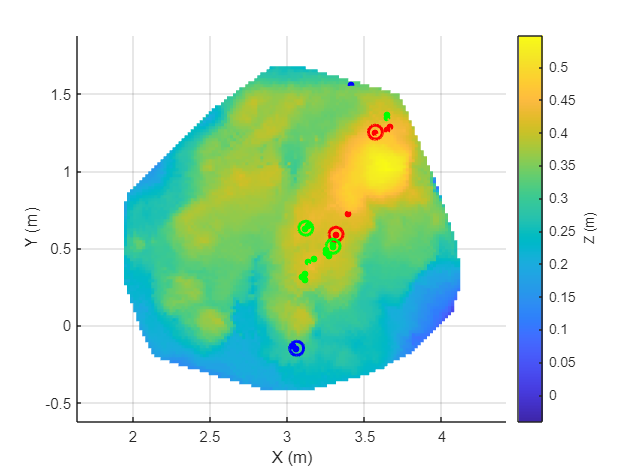

figure;
hold on;
surf(X, Y, F, 'EdgeColor', 'none');
%colorbar;
a=colorbar;
a.Label.String = 'Z (m)';

% Labels and formatting
axis equal;
view(2);
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z');
%title('Overlayed Surf Plots');
grid on;
%shading interp;
%camlight;
lighting gouraud;
hold on;
scatter3(x_matches4, y_matches4, z_matches4-0.28, 20, "red", "filled");
scatter3(x_matches5, y_matches5, z_matches5-0.28, 20, "green", "filled");
scatter3(x_matches6, y_matches6, z_matches6-0.28, 20, "blue", "filled");
theta = linspace(0,2*pi,200);
xc = x_matches6(1); yc = y_matches6(1);     % axes coordinates where you want the label
r = 0.045;             % mm (convert to your axes units)

plot3(xc + r*cos(theta), yc + r*sin(theta), ...
      ones(size(theta))*max(zlim), ...   % float above everything
      'b','LineWidth',2);

xc = x_matches4(1); yc = y_matches4(1);     % axes coordinates where you want the label
r = 0.045;             % mm (convert to your axes units)

plot3(xc + r*cos(theta), yc + r*sin(theta), ...
      ones(size(theta))*max(zlim), ...   % float above everything
      'r','LineWidth',2);

xc = x_matches4(3); yc = y_matches4(3);     % axes coordinates where you want the label
r = 0.045;             % mm (convert to your axes units)

plot3(xc + r*cos(theta), yc + r*sin(theta), ...
      ones(size(theta))*max(zlim), ...   % float above everything
      'r','LineWidth',2);

xc = x_matches5(9); yc = y_matches5(9);     % axes coordinates where you want the label
r = 0.045;             % mm (convert to your axes units)

plot3(xc + r*cos(theta), yc + r*sin(theta), ...
      ones(size(theta))*max(zlim), ...   % float above everything
      'g','LineWidth',2);

xc = x_matches5(11); yc = y_matches5(11);     % axes coordinates where you want the label
r = 0.045;             % mm (convert to your axes units)

plot3(xc + r*cos(theta), yc + r*sin(theta), ...
      ones(size(theta))*max(zlim), ...   % float above everything
      'g','LineWidth',2);
hold off

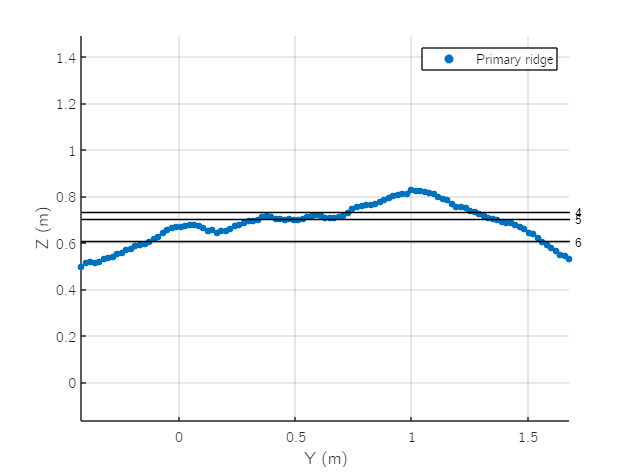


scatter(output.Y_interest_all, output.Z_interest_all+0.28,20, 'filled');
xlabel('Y (m)');
ylabel('Z (m)');
grid on
axis equal
set(gca, 'FontName', 'CMU Bright');
hold on
xl = xlim;

y = 0.73;
plot(xl, [y y], 'k', 'LineWidth', 1);
text(xl(2) + 0.01*(xl(2)-xl(1)), y, '4', ...
    'FontSize', 8, ...
    'HorizontalAlignment', 'left', ...
    'VerticalAlignment', 'middle');

% --- Core 5 ---
y = 0.70;
plot(xl, [y y], 'k', 'LineWidth', 1);
text(xl(2) + 0.01*(xl(2)-xl(1)), y, '5', ...
    'FontSize', 8, ...
    'HorizontalAlignment', 'left', ...
    'VerticalAlignment', 'middle');

% --- Core 6 ---
y = 0.605;
plot(xl, [y y], 'k', 'LineWidth', 1);
text(xl(2) + 0.01*(xl(2)-xl(1)), y, '6', ...
    'FontSize', 8, ...
    'HorizontalAlignment', 'left', ...
    'VerticalAlignment', 'middle');

legend('Primary ridge')
hold off